# Premier League Team Information

The spreadsheet `EPLteaminfo.xlsx` contains information about each team in the English Premier League during the 2015-2016 season, including total player payroll (in millions of pounds), manager at the end of the season, manager's hire date, and manager's nationality.

## Import team management data.

Import the spreadsheet `EPLteams.xlsx` as a table.

teaminfo = readtable('EPLteams.xlsx');

Change the name of the payroll variable to remove extraneous characters.

teaminfo.Properties.VariableNames{2} = 'Payroll';

## Import league results.

Load the file `EPLresults.mat`. Join the table containing season results with the table of team infomation.

load EPLresults
EPL = join(teaminfo,EPL,'Keys','Team')

EPL =              Team             Payroll            Manager            ManagerHireDate    ManagerNationality    HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA    Points    GD 
    ______________________    _______    _______________________    _______________    __________________    ________    _________    __________    ______    ______    ________    _________    __________    ______    _

## Explore effect of manager hire date

Plot the each team’s number of home wins by their manager’s hire date.

plot(EPL.ManagerHireDate,EPL.HomeWins,'*')
xlabel('Manager Hire Date')
ylabel('Home Wins')

Adjust the x-axis limits to ignore the outlier.

t1 = datetime(2012,7,1);
t2 = datetime(2016,7,1);
xlim([t1,t2])

Add a vertical line at the season start date. Do managers hired before or after the season start appear to have more home wins?

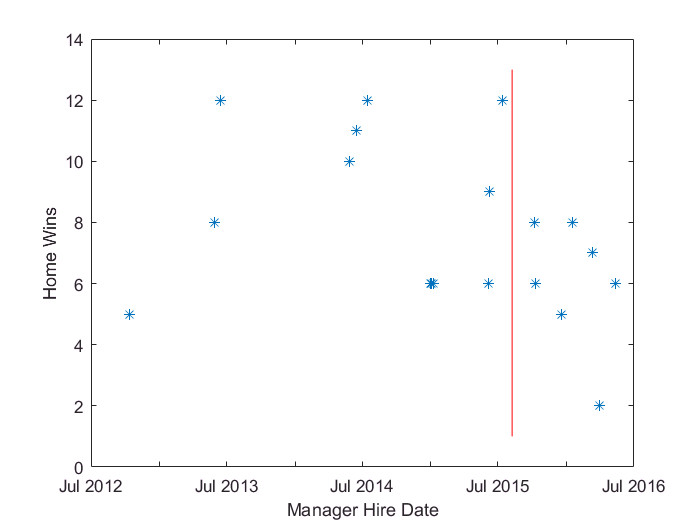

seasonStart = datetime(2015,8,8);
hold on
plot([seasonStart seasonStart],[1 13],'r')
hold off

## Seasonality of manager hiring

In which months are managers commonly hired?

hireMonth = month(EPL.ManagerHireDate);
histogram(hireMonth)
title('EPL Managers'' Month of Hire')
xlim([0 13])
ylim([0 5])

Modify the x-axis labels.

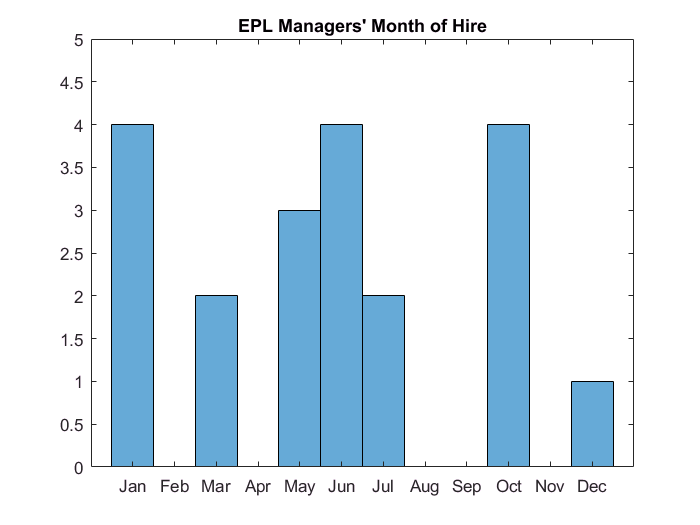

t = datetime(2016,1:12,1);
mths = cellstr(t,'MMM');
xticks(1:12)
xticklabels(mths)

## Manager nationality

Convert the countries to a categorical array.

EPL.ManagerNationality = categorical(EPL.ManagerNationality);
ctry = EPL.ManagerNationality;

What set of countries are represented by the managers? How many managers are from each country?

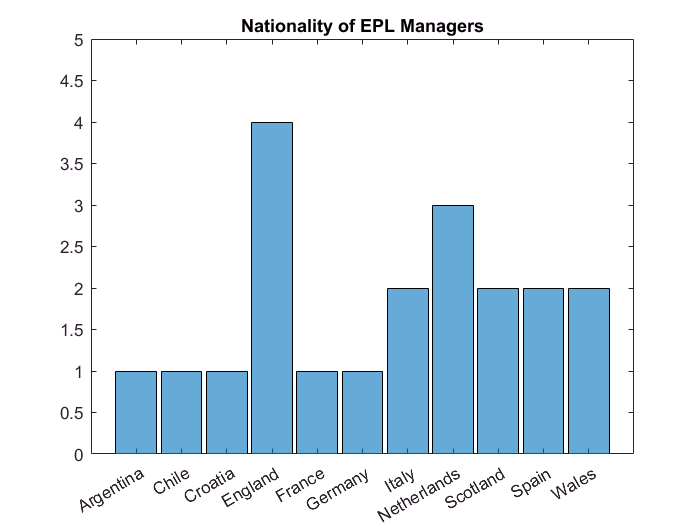

histogram(ctry)
title('Nationality of EPL Managers')
ylim([0 5])

How many managers are from the UK?

catsUK = {'England','Scotland','Wales'};
natUK = mergecats(ctry,catsUK,'UK');
nnz(natUK == 'UK')

ans = 8

What is the average number of home wins for UK managers?

mean(EPL.HomeWins(natUK == 'UK'))

ans = 5.6250